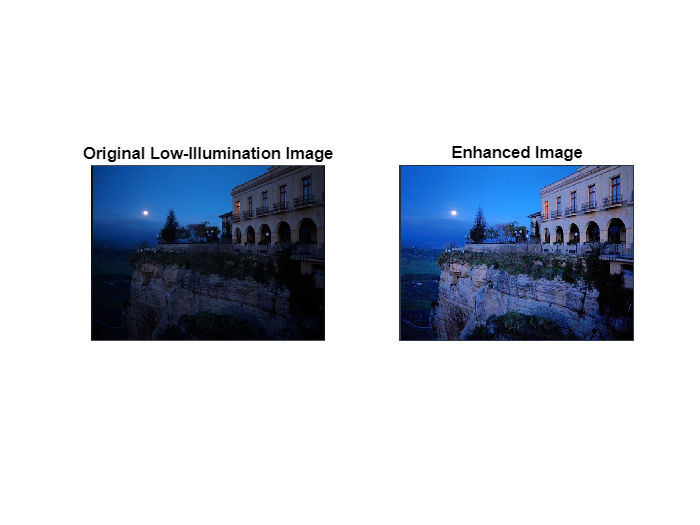

% Read the input low-illumination image
inputImage = imread('test.png'); % Replace with your image file name
inputImage = im2double(inputImage);

% Convert the image to HSV color space
hsvImage = rgb2hsv(inputImage);
V = hsvImage(:,:,3);

% Set parameters for the Gaussian filter
sigma = 15; % Increased sigma for smoother initial illumination estimate
filterSize = 2 * ceil(3 * sigma) + 1;

% Estimate the initial environmental light using Gaussian filter
L_ini = imgaussfilt(V, sigma, 'FilterSize', filterSize);

% Initialize parameters
t_min = 0.1;
delta = 0.02; % Reduced delta for finer adjustments
maxIterations = 50; % Increased number of iterations for finer control
L_step = (128 - mean(L_ini(:))) / maxIterations;

% Define information loss constraint threshold
N_th = 0.01 * numel(V); % Reduced threshold for better control of information loss

% Initialize light-scattering attenuation rate
t = t_min;

% Initialize environmental light
L = L_ini;

% Iterative adjustment process
for iter = 1:maxIterations
    % Calculate the restored image R
    R = (V - L) ./ max(t, t_min) + L;
    
    % Calculate information loss
    upflow = sum(R(:) > 1);
    underflow = sum(R(:) < 0);
    N_loss = upflow + underflow;
    
    if N_loss < N_th
        break;
    end
    
    % Adjust light-scattering attenuation rate and environmental light
    t = t + delta;
    if upflow > underflow
        L = L + L_step;
    else
        L = L - L_step;
    end
end

% Refine the parameters using a guided filter for better edge preservation
L_refined = imguidedfilter(L, 'DegreeOfSmoothing', 0.001);
t_refined = imguidedfilter(t, 'DegreeOfSmoothing', 0.001);

% Restore the final image
R_final = (V - L_refined) ./ max(t_refined, t_min) + L_refined;

% Apply Histogram Equalization for better contrast while preserving natural look
R_final = histeq(R_final);

% Combine the enhanced V channel with the original H and S channels
hsvImage(:,:,3) = R_final;
enhancedImage = hsv2rgb(hsvImage);

% Display the original and enhanced images
figure;
subplot(1, 2, 1), imshow(inputImage), title('Original Low-Illumination Image');
subplot(1, 2, 2), imshow(enhancedImage), title('Enhanced Image');


% Save the enhanced image
imwrite(enhancedImage, 'enhanced_image.jpg');